clear; clear path; clc;
load ../data/plantTF.mat

syms s P

G(s,P) = (200*s+10^6)/(s^2*(s^2+200*s+10^6))

$$G(s, P) = \frac{200\,s+1000000}{s^{2}\,\left(s^{2}+200\,s+1000000\right)}$$


C(s,P) = P

$$C(s, P) = P$$


L(s,P)=C*G

$$L(s, P) = \frac{P\,\left(200\,s+1000000\right)}{s^{2}\,\left(s^{2}+200\,s+1000000\right)}$$

T(s,P) = G/(1+L);

% Compute simplified symbolic expression
T(s,P) = simplifyFraction(T)

$$T(s, P) = \frac{200\,\left(s+5000\right)}{s^{4}+200\,s^{3}+1000000\,s^{2}+200\,P\,s+1000000\,P}$$


numerator(s,P) = 200*(s+5000)

$$numerator(s, P) = 200\,s+1000000$$

denominator(s,P) = s^4+200*s^3+10^6*s^2+200*P*s+10^6;

% for i = 1:10
%     denominatorUp = subs(denominator,[P],100000*[i]);
%     poles =double(solve(denominatorUp==0,s))
%     clf; hold on; grid on;
%     plot(real(poles(1)),imag(poles(1)),'*')
%     axis([-0.01 0 -0.1 0.1])
% end


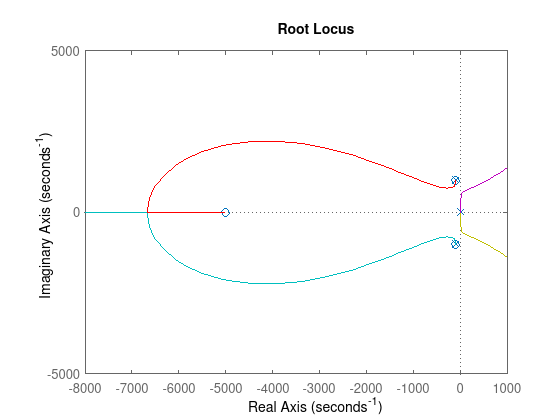

% fsurf(denomintor)
% title("denominator space")
% % var = vpasolve(denomintor==0,s)
Ts = Ps/(1+Ps);
figure(1); clf; hold on; grid on;
rlocus(Ts);
axis([-8000 1000 -5000 5000])

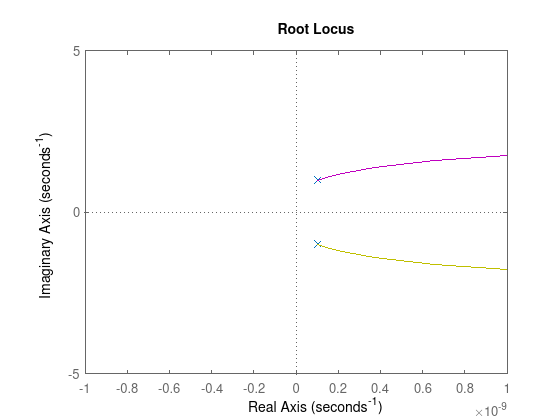


figure(2); clf; hold on; grid on;
Ts = Ps/(1+Ps);
rlocus(Ts)
axis([-1E-9 1E-9 -5 5])

## Analytical Stuff

syms y P;
eq1 = y^2+5000*y+6250000-200*P*(y-2500)
% this solves to 
y1 = 100*(P+sqrt((P-100)*P)+25)
